# CDL Channel Model Customization with Ray Tracing

This example shows how to customize the CDL channel model parameters by using the output of a ray tracing analysis. The example shows how to: 

- Specify the location of a transmitter and a receiver in a 3D environment.

- Use ray tracing to calculate the geometric aspects of the channel: number of rays, angles, delays and attenuations.

- Configure the CDL channel model with the result of ray tracing analysis.

- Specify the channel antenna arrays using Phased Array System Toolbox™.

- Visualize the transmit and receive array radiation patterns based on singular value decomposition of a perfect channel estimate.

## Base Station and UE Configuration

The example assumes that both the base station and the UE use rectangular arrays. The array orientations are specified as a pair of values representing azimuth and elevation. Both angles are in degrees.

fc = 6e9;                             % carrier frequency (Hz)
bsPosition = [45.495066,-73.561279]; % [22.287495, 114.140706]; % lat, lon
% height = 57m
bsAntSize = [1 1]; % [8 8];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg

uePosition = [45.494794,-73.559819]; % [22.287323,114.140859];  % lat, lon
% height = 15m
ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

ue2Position = [45.495949,-73.561362]; % [22.287323,114.140859];  % lat, lon
% height = 17m
ue2AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue2ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

reflectionsOrder = 1;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 30; % 15; % subcarrier spacing
NRB = 51; % number of resource blocks, SCS*NRB*12 MHz bandwidth for transmission

## Import and Visualize 3-D Environment with Buildings for Ray Tracing

Launch Site Viewer with buildings in ETS. For more information about the osm file, see [1].

addpath('osmFile')
if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","map.osm");    
end

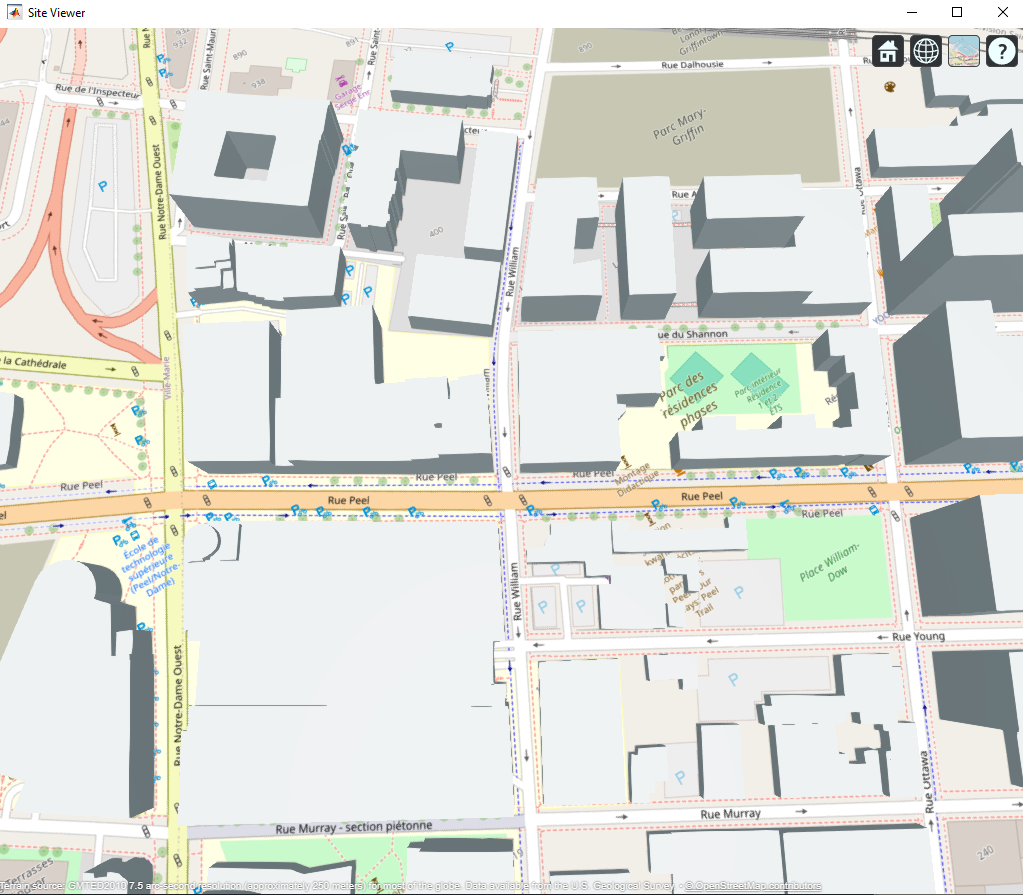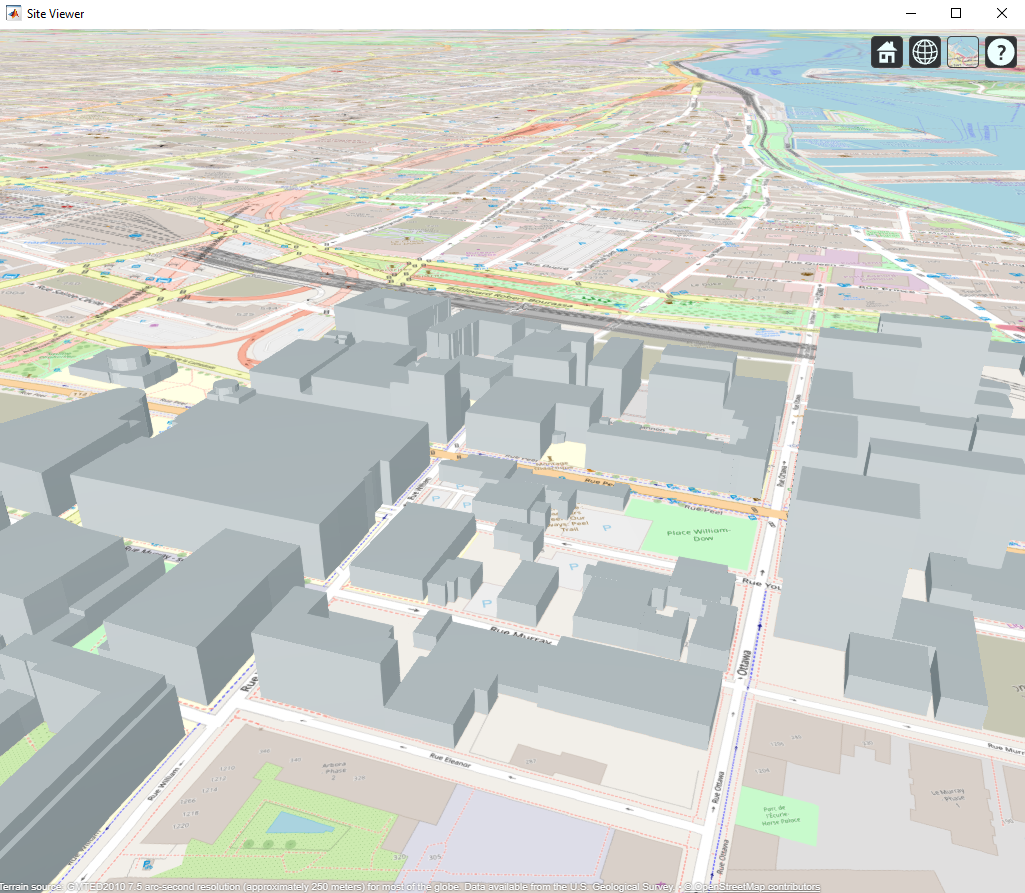

## Create Base Station and UE

Locate the base station and the UE on the map.

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);

ueSite = rxsite("Name","UE1", ...
    "Latitude",uePosition(1),"Longitude",uePosition(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ueArrayOrientation(1:2));

ue2Site = rxsite("Name","UE2", ...
    "Latitude",ue2Position(1),"Longitude",ue2Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue2ArrayOrientation(1:2));

Visualize the location of the base station and the UE. The base station is on top of a building.

show(bsSite);
show(ueSite);
show(ue2Site);

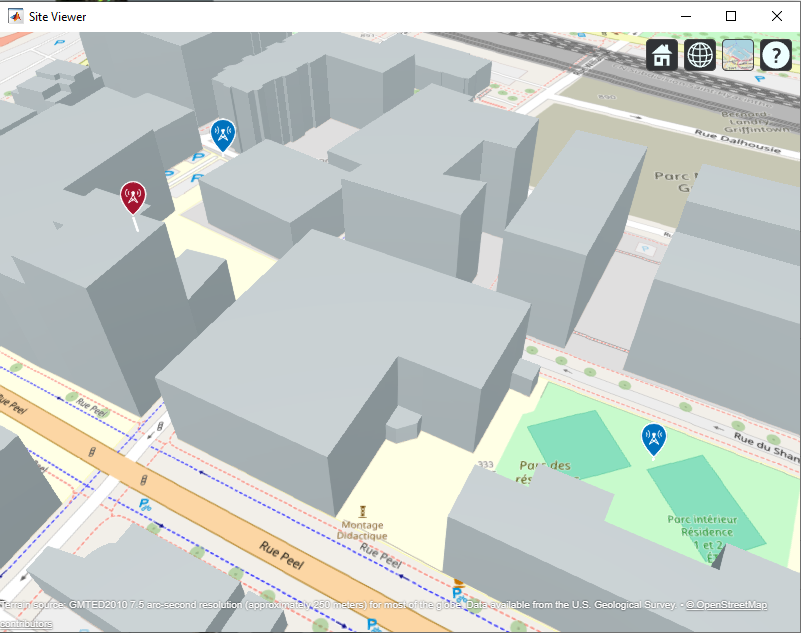

## Ray Tracing Analysis

Perform ray tracing analysis using the shooting and bouncing rays (SBR) method. The SBR method includes effects from surface reflections and diffractions but does not include effects from refraction or scattering.

pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
rays = raytrace(bsSite,ueSite,pm,"Type","pathloss");
rays2 = raytrace(bsSite,ue2Site,pm,"Type","pathloss");

Display the rays in Site Viewer.

plot(rays{1})
plot(rays2{1})

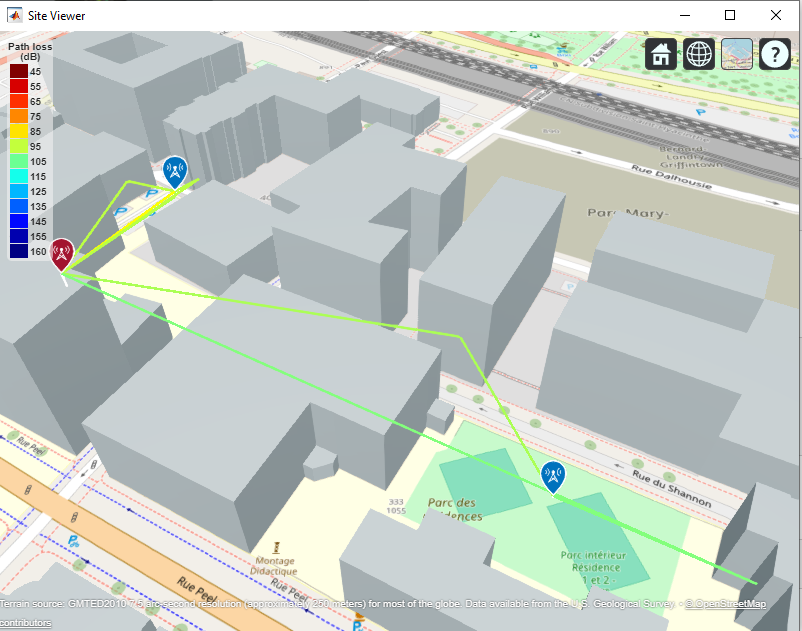

From the obtained rays, get the times of arrival, the average path gains, and the angles of departure and arrival. For simplicity, normalize the propagation delay so that the first path occurs at time 0 sec, corresponding to no delay. Use the path loss to obtain the average path gains. 

pathToAs = [rays{1}.PropagationDelay]-min([rays{1}.PropagationDelay]);  % Time of arrival of each ray (normalized to 0 sec)
avgPathGains  = -[rays{1}.PathLoss];                                    % Average path gains of each ray
pathAoDs = [rays{1}.AngleOfDeparture];                                  % AoD of each ray
pathAoAs = [rays{1}.AngleOfArrival];                                    % AoA of each ray
isLOS = any([rays{1}.LineOfSight]);                                     % Line of sight flag

## Set Up CDL Channel Model

Configure the CDL channel model with the information generated by the ray tracing analysis. Set the `DelayProfile` property to `'Custom'` to specify the path delays, the average path gains and the angles of arrival and departure (both in azimuth and zenith).

When configuring the channel model, take into account that:

- The ray tracer finds individual rays between the base station and the UE, while the CDL channel models clusters of rays whose properties are determined by the cluster average path gain (`AveragePathGains`), average angles of arrival and departure (`AnglesAoA`, `AnglesZoA`, `AnglesAoD`, and `AnglesZoD`), and the spread of the rays in the cluster (`AngleSpreads`). The information retrieved from the ray tracing analysis for individual rays configures the cluster average values of the CDL channel.

- The ray tracer performs a static analysis, while the CDL channel models UE movement. Therefore, the CDL channel introduces small-scale fading.

- The path gains obtained from ray tracing are considered as average path gains. Therefore, because of fading, instantaneous channel path gains will differ from the average values, but over long simulations their mean value will match the specified average path gains when using isotropic antennas.

- The CDL channel uses zenith angles, while the ray tracing analysis returns elevation angles, therefore you must convert between the two.

- If any of the calculated rays is a line of sight (LOS) ray (no reflection), set the `HasLOSCluster` CDL channel property to `true`. For LOS cases, the CDL model splits the first path into two components, one being LOS and the other having a Rayleigh fading characteristic. This results in a combined Rician fading characteristic. Therefore, in LOS cases, when you specify *N* rays, the CDL channel models *N*+1 paths internally.

channel = nrCDLChannel;
channel.DelayProfile = 'Custom';
channel.PathDelays = pathToAs;
channel.AveragePathGains = avgPathGains;
channel.AnglesAoD = pathAoDs(1,:);       % azimuth of departure
channel.AnglesZoD = 90-pathAoDs(2,:);    % channel uses zenith angle, rays use elevation
channel.AnglesAoA = pathAoAs(1,:);       % azimuth of arrival
channel.AnglesZoA = 90-pathAoAs(2,:);    % channel uses zenith angle, rays use elevation
channel.HasLOSCluster = isLOS;
channel.CarrierFrequency = fc;
channel.NormalizeChannelOutputs = false; % do not normalize by the number of receive antennas, this would change the receive power
channel.NormalizePathGains = false;      % set to false to retain the path gains

Specify the channel antenna arrays by using Phased Array System Toolbox array objects. The array orientation properties of the CDL channel model use azimuth and downtilt while the `ueArrayOrientation` and `bsArrayOrientation` objects use azimuth and elevation. Therefore, convert the elevation to downtilt by changing the sign.

c = physconst('LightSpeed');
lambda = c/fc;

% UE array (single panel)
ueArray = phased.NRRectangularPanelArray('Size',[ueAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
ueArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element
channel.ReceiveAntennaArray = ueArray;
channel.ReceiveArrayOrientation = [ueArrayOrientation(1); (-1)*ueArrayOrientation(2); 0];  % the (-1) converts elevation to downtilt

% Base station array (single panel)
bsArray = phased.NRRectangularPanelArray('Size',[bsAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
bsArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element;  {phased.NRAntennaElement('PolarizationAngle',-45) phased.NRAntennaElement('PolarizationAngle',45)}; % cross polarized elements
channel.TransmitAntennaArray = bsArray;
channel.TransmitArrayOrientation = [bsArrayOrientation(1); (-1)*bsArrayOrientation(2); 0];   % the (-1) converts elevation to downtilt

## Set Channel Sampling Rate

The signal going through the channel determines the channel sampling rate. Consider a signal with subcarrier spacing of 30 kHz and 51 resource blocks (RBs), equivalent to a bandwidth of 20 MHz (30e3*51e12 Hz for transmission). To obtain the sampling rate, call the `nrOFDMInfo` function.

ofdmInfo = nrOFDMInfo(NRB,SCS);

channel.SampleRate = ofdmInfo.SampleRate;

## True Channel (when setting ChannelFiltering = false)

Setting the `ChannelFiltering` property to `false`  to get the channel path gains without sending a signal through the channel.

channel.ChannelFiltering = false;
[pathGains,sampleTimes] = channel();
% pathGains = 2x2 = N_cs x N_P x N_T x N_R
                    % N_cs - number of channel snapshots
                    % N_P - number of paths
                    % N_T - number of transmit antennas
                    % N_R - number of receive antennas

Plot the path gains returned by the channel. Compare the results with the specified average path gains obtained from the ray attenuation values. 

- For LOS cases, because the first two paths correspond to the first ray, the first two paths must be added together.

- The CDL channel model is a statistical channel model and considers UE motion. Therefore, the returned path gains are the instantaneous gains. The path gains from the ray tracing analysis are interpreted as average path gains by the channel model.

- The instantaneous path gains returned by the channel model include the gain of the antenna element in the direction of each ray. The custom path gains obtained from the ray tracing analysis do not include the antenna element gain. Therefore, in the mean, the channel path gains match the average gains only for isotropic antenna elements.

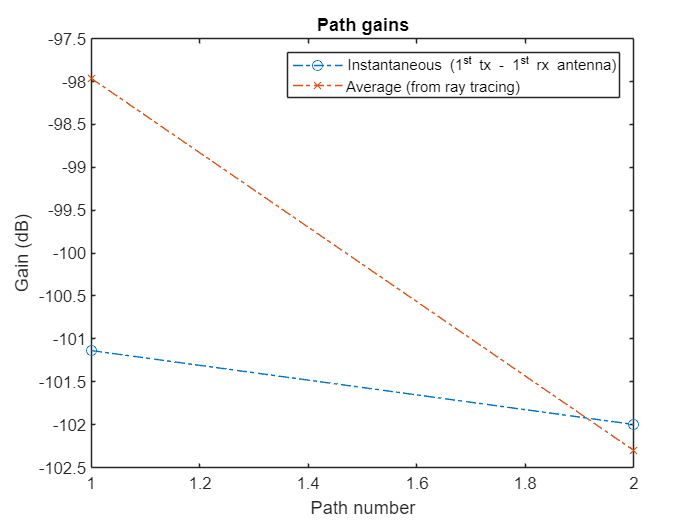

pg=permute(pathGains,[2 1 3 4]); % first dimension is the number of paths
% pg = N_p x N_cs x N_t x N_r == 2x2
if isLOS
    % in LOS cases sum the first to paths, they correspond to the LOS ray
    pg = [sum(pg(1:2,:,:,:)); pg(3:end,:,:,:)];
end
pg = abs(pg).^2;  % N_p x N_cs x N_t == 2x2x2
plot(pow2db(pg(:,1,1,1)),'o-.');hold on
plot(avgPathGains,'x-.');hold off
legend("Instantaneous (1^{st} tx - 1^{st} rx antenna)","Average (from ray tracing)")
xlabel("Path number"); ylabel("Gain (dB)")
title('Path gains')

Obtain a perfect channel estimate for slot 0.

pathFilters = getPathFilters(channel);
nSlot = 0;
[offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
hest = nrPerfectChannelEstimate(pathGains,pathFilters,NRB,SCS,nSlot,offset,sampleTimes);

Plot the channel response in time and frequency between the first transmit and the first receive antenna. This plot shows how the channel behaves in time and frequency. For low Doppler shifts, the channel doesn't change much during the observation period of one slot.

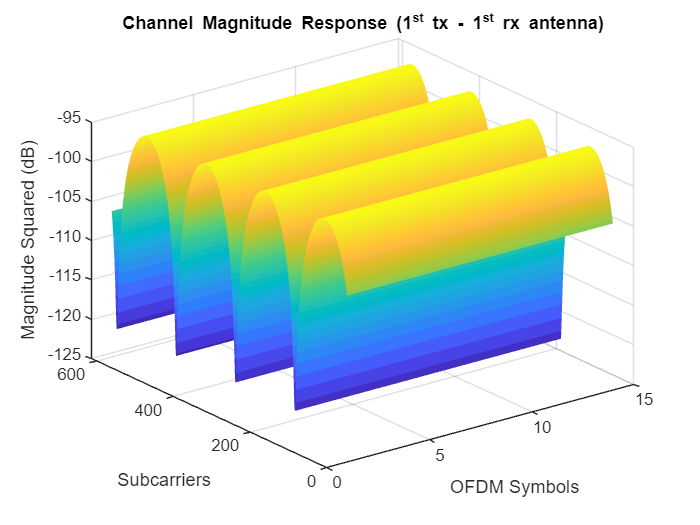

surf(pow2db(abs(hest(:,:,1,1)).^2));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
title('Channel Magnitude Response (1^{st} tx - 1^{st} rx antenna)');

isequal(hest(:,1,1,1), hest(:,14,1,1))

ans = logical
   1

In this example, channel ramains the same through 14 OFDM symbols. 

But in example [https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html,](https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html,) channel slightly changes through each one of 14 OFDM symbols.

## Generating transmit signal (when setting ChannelFiltering = true)

transmit = s (symbol)

s_rg -- resource grid

S_rg : f-domain

receive  = r

X, Y : in machine learning 

carrier = nrCarrierConfig;
carrier.NSizeGrid = 51;            % Bandwidth in number of resource blocks (51 RBs at 30 kHz SCS for 20 MHz BW)
carrier.SubcarrierSpacing = 30;    % 15, 30, 60, 120, 240 (kHz)
carrier.CyclicPrefix = "Normal";   % "Normal" or "Extended" (Extended CP is relevant for 60 kHz SCS only)
carrier.NCellID = 2;  

% PDSCH and DM-RS configuration
pdsch = nrPDSCHConfig;
pdsch.PRBSet = 0:carrier.NSizeGrid-1; % PDSCH PRB allocation
pdsch.SymbolAllocation = [0, carrier.SymbolsPerSlot];           % PDSCH symbol allocation in each slot
pdsch.MappingType = "A";     % PDSCH mapping type ("A"(slot-wise),"B"(non slot-wise))
pdsch.NID = carrier.NCellID;
pdsch.RNTI = 1;
pdsch.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
pdsch.NumLayers = 1;            % Number of PDSCH transmission layers
pdsch.Modulation = "16QAM";                       % "QPSK", "16QAM", "64QAM", "256QAM"

% DM-RS configuration
pdsch.DMRS.DMRSPortSet = 0:pdsch.NumLayers-1; % DM-RS ports to use for the layers
pdsch.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
pdsch.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
pdsch.DMRS.DMRSAdditionalPosition = 1; % Additional DM-RS symbol positions (max range 0...3)
pdsch.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
pdsch.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
pdsch.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
pdsch.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)


% Generate DM-RS indices and symbols
dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

% Create resource grid
pdschGrid = nrResourceGrid(carrier);

% Map PDSCH DM-RS symbols to the grid
pdschGrid(dmrsIndices) = dmrsSymbols;

% OFDM-modulate associated resource elements
txWaveform = nrOFDMModulate(carrier,pdschGrid);

channel2 = channel

channel2 =   nrCDLChannel with properties:

                 DelayProfile: 'Custom'
                   PathDelays: [0 2.1585e-07]
             AveragePathGains: [-97.9612 -102.3009]
                    AnglesAoD: [5.8974 -20.7484]
                    AnglesAoA: [117.7651 -36.4531]
                    AnglesZoD: [107.8816 102.2768]
                    AnglesZoA: [72.1196 77.7250]
                HasLOSCluster: false
                 AngleSpreads: [5 11 3 3]
                  RayCoupling: 'Random'
                          XPR: 10
                InitialPhases: 'Random'
             CarrierFrequency: 6.0000e+09
          MaximumDopplerShift: 5
          UTDirectionOfTravel: [2×1 double]
                   SampleRate: 30720000
         TransmitAntennaArray: [1×1 phased.NRRectangularPanelArray]
     TransmitArrayOrientation: [3×1 double]
          ReceiveAntennaArray: [1×1 phased.NRRectangularPanelArray]
      Receive

release(channel2)
channel2.ChannelFiltering = true;
[rxWaveform,pathGains2,sampleTimes2] = channel2(txWaveform);
% pathGains2 = 1x2 = N_cs x N_P x N_T x N_R
                    % N_cs - number of channel snapshots
                    % N_P - number of paths
                    % N_T - number of transmit antennas
                    % N_R - number of receive antennas
                    

check if pathGains here is qual to first pathGains. (not equal - due to the randomness accordig to average pathloss?) 

isequal(pathGains2, pathGains)

ans = logical
   0

### Add noise

% waveformInfo = nrOFDMInfo(carrier); == ofdmInfo
% channel.SampleRate = waveformInfo.SampleRate;
SNRdB = 0; % dB
SNR = 10^(SNRdB/10); % Calculate linear SNR
N0 = 1/sqrt(1*double(ofdmInfo.Nfft)*SNR); % simParameters.NRxAnts = 1
noise = N0*randn(size(rxWaveform),"like",rxWaveform);
rxWaveform = rxWaveform + noise;

### True channel 

% Get path filters for perfect channel estimation
pathFilters2 = getPathFilters(channel);
[offset,~] = nrPerfectTimingEstimate(pathGains2,pathFilters2);

rxWaveform = rxWaveform(1+offset:end, :);

TrueChannelGrid = nrPerfectChannelEstimate(carrier,pathGains2, ...
    pathFilters2,offset,sampleTimes2);

H_true = TrueChannelGrid(:,:,1,1);
size(H_true)

ans =    612    14


surf(pow2db(abs(TrueChannelGrid(:,:,1,1)).^2));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
title('Channel Magnitude Response (1^{st} tx - 1^{st} rx antenna)');

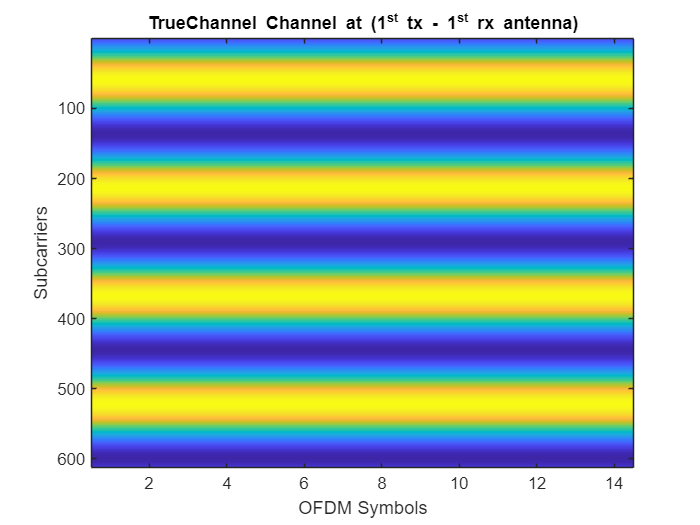

imagesc(abs(TrueChannelGrid(:,:,1,1)).^2);
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');
title('TrueChannel Channel at (1^{st} tx - 1^{st} rx antenna)');

The channel also remains through 14 OFDM symbols, even pathGains2 ~= pathGains. So what is the difference between this and the CNN example? is it the Doppler f_D?

isequal(TrueChannelGrid(:,1,1,1), hest(:,5,1,1))

ans = logical
   1

### OFDM-demodulate the received data to recreate the resource grid

rxGrid = nrOFDMDemodulate(carrier,rxWaveform);


% Pad the grid with zeros in case an incomplete slot has been demodulated
[K,L,R] = size(rxGrid);
if (L < carrier.SymbolsPerSlot)
    rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
end

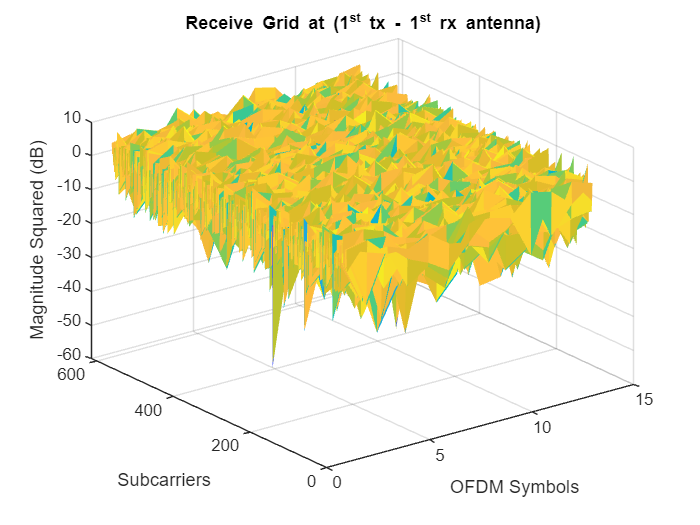

surf(pow2db(abs(rxGrid(:,:,1,1)).^2));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
title('Receive Grid at (1^{st} tx - 1^{st} rx antenna)');

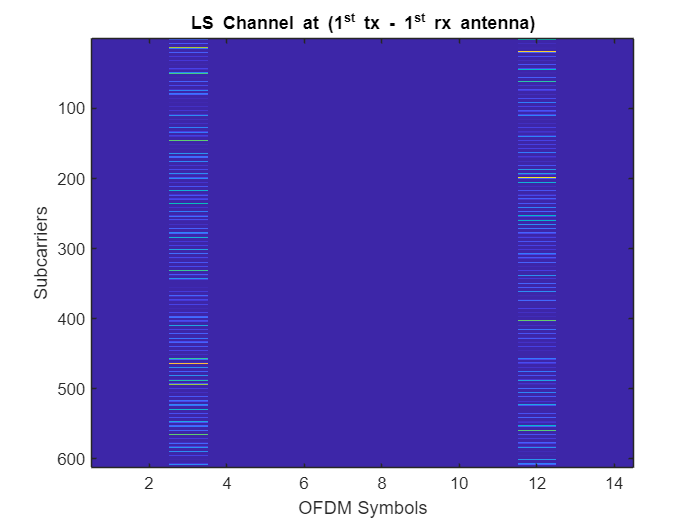

[H_equalized, H_linear] = Lin_Interpolate(rxGrid, dmrsIndices, dmrsSymbols);

imagesc(abs(H_equalized(:,:,1,1)).^2);
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');
title('LS Channel at (1^{st} tx - 1^{st} rx antenna)');

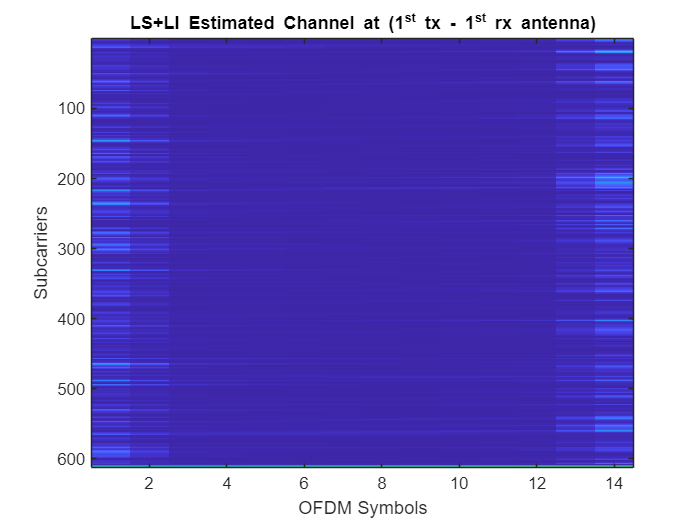

imagesc(abs(H_linear(:,:,1,1)).^2);
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('Magnitude Squared (dB)');
title('LS+LI Estimated Channel at (1^{st} tx - 1^{st} rx antenna)');

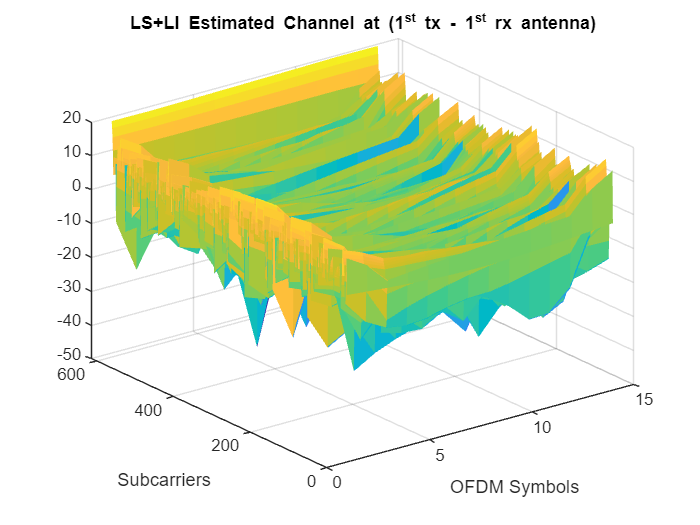

surf(pow2db(abs(H_linear(:,:,1,1)).^2));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');
title('LS+LI Estimated Channel at (1^{st} tx - 1^{st} rx antenna)');

save("Data\test.mat",'H_linear', 'H_equalized', 'H_true')

## Get Beamforming Weights

Calculate the beamforming weights using singular value decomposition (SVD). Assume 1 layer. The `getBeamformingWeights` function averages the channel conditions over a number of resource blocks, starting at an offset from the edge of the band (first subcarrier), enabling subband beamforming.

nLayers = 1;
scOffset = 0;   % no offset
noRBs = 1;      % average channel conditions over 1 RB to calculate beamforming weights
[wbs,wue,~] = getBeamformingWeights(hest,nLayers,scOffset,noRBs);

## Plot Radiation Patterns

Plot the radiation patterns obtained for the UE and the base station.

% Plot UE radiation pattern
ueSite.Antenna = clone(channel.ReceiveAntennaArray); % need a clone, otherwise setting the Taper weights would affect the channel array
ueSite.Antenna.Taper = wue;
pattern(ueSite,fc,"Size",4);

% Plot BS radiation pattern
bsSite.Antenna = clone(channel.TransmitAntennaArray); % need a clone, otherwise setting the Taper weights would affect the channel array
bsSite.Antenna.Taper = wbs;
pattern(bsSite,fc,"Size",5);

## References

[1] The osm file is downloaded from [https://www.openstreetmap.org](https://www.openstreetmap.org/), which provides access to crowd-sourced map data all over the world. The data is licensed under the Open Data Commons Open Database License (ODbL), [https://opendatacommons.org/licenses/odbl/](https://opendatacommons.org/licenses/odbl/). 

## Local Functions

function [wtx,wrx,D] = getBeamformingWeights(hEst,nLayers,scOffset,noRBs)
% Get beamforming weights given a channel matrix hEst and the number of
% layers nLayers. One set of weights is provided for the whole bandwidth.
% The beamforming weights are calculated using singular value (SVD)
% decomposition.
%
% Only part of the channel estimate is used to get the weights, this is
% indicated by an offset SCOFFSET (offset from the first subcarrier) and a
% width in RBs (NORBS).

% Average channel estimate
[~,~,R,P] = size(hEst);
%H = permute(mean(reshape(hEst,[],R,P)),[2 3 1]);

scNo = scOffset+1;
hEst = hEst(scNo:scNo+(12*noRBs-1),:,:,:);
H = permute(mean(reshape(hEst,[],R,P)),[2 3 1]);

% SVD decomposition
[U,D,V] = svd(H);
wtx = V(:,1:nLayers).';
wrx = U(:,1:nLayers)';
end

function [H_equalized, H_linear] = Lin_Interpolate(Y_noise, pilot_Indices, pilot_Symbols)
% Perform linear interpolation of the grid and input the result to the
% neural network This helper function extracts the DM-RS symbols from
% dmrsIndices locations in the received grid rxGrid and performs linear
% interpolation on the extracted pilots.

    % Obtain pilot symbol estimates
    dmrsRx = Y_noise(pilot_Indices);
    dmrsEsts = dmrsRx .* conj(pilot_Symbols);

    % Create empty grids to fill after linear interpolation
    [H_equalized, rxDMRSGrid, H_linear] = deal(zeros(size(Y_noise)));
    rxDMRSGrid(pilot_Indices)  = pilot_Symbols;
    H_equalized(pilot_Indices) = dmrsEsts;
    
    % Find the row and column coordinates for a given DMRS configuration
    [rows,cols] = find(rxDMRSGrid ~= 0);
    dmrsSubs = [rows,cols,ones(size(cols))];
    [l_hest,k_hest] = meshgrid(1:size(H_linear,2),1:size(H_linear,1));

    % Perform linear interpolation
    f = scatteredInterpolant(dmrsSubs(:,2),dmrsSubs(:,1),dmrsEsts);
    H_linear = f(l_hest,k_hest);

end


*Copyright 2020-2023 The MathWorks, Inc.*